x_original_low = x;
xf_original_low= xf;
fc = 4000;           % cutoff in Hz
fs_low = 48000;          % sampling rate
N_low = 101;             % filter length

h_low = lowpass_fir(fc, fs_low, N_low);               % design filter
x_low_filtered = conv(x, h_low, 'same');          % apply FIR filter via convolution

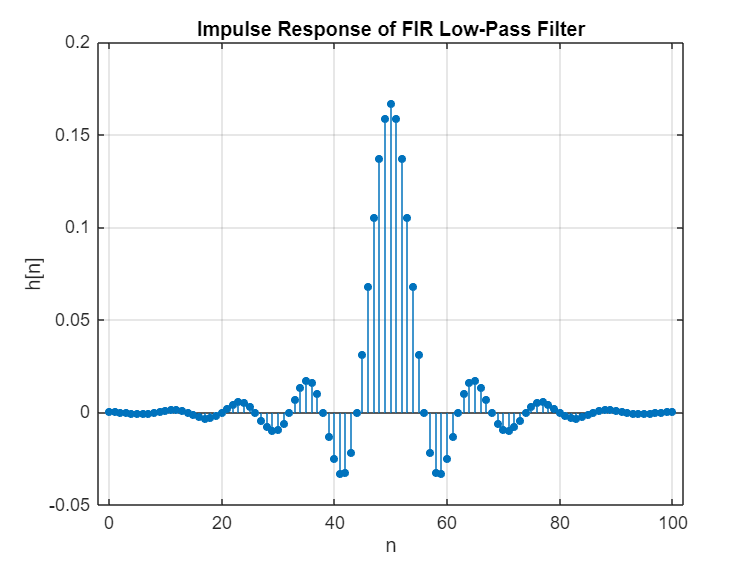

figure;
stem(0:N_low-1, h_low, 'filled', 'MarkerSize', 4);
xlabel('n'); ylabel('h[n]');
title('Impulse Response of FIR Low-Pass Filter');
grid on;

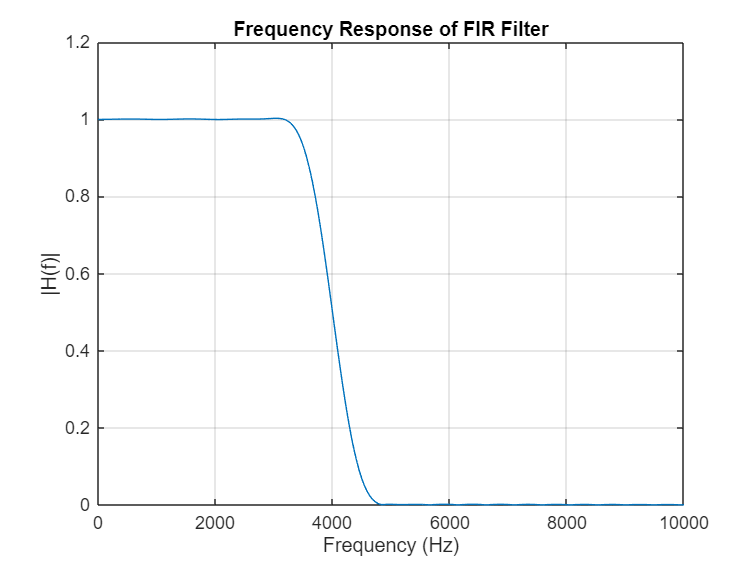

% Frequency axis (same as FFT)
N_fft_low = 1024;
f_axis_low = (0:N_fft_low-1) * fs_low / N_fft_low;

% Compute FFT of filter
H_f_low = abs(fft(h_low, N_fft_low));

% Plot
figure;
plot(f_axis_low, H_f_low);
xlabel('Frequency (Hz)');
ylabel('|H(f)|');
title('Frequency Response of FIR Filter');
xlim([0 10000]);
grid on;

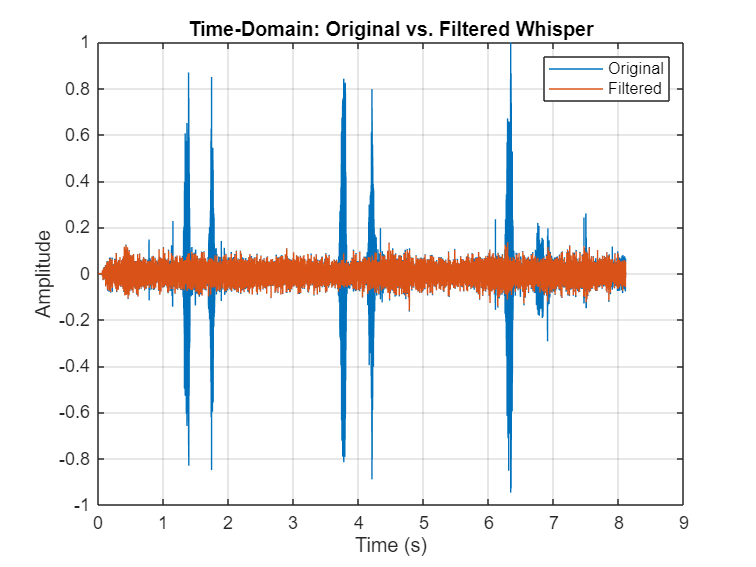

figure;
plot(t, x_original_low); hold on;
plot(t, x_low_filtered);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain: Original vs. Filtered Whisper');
legend('Original','Filtered');
grid on;

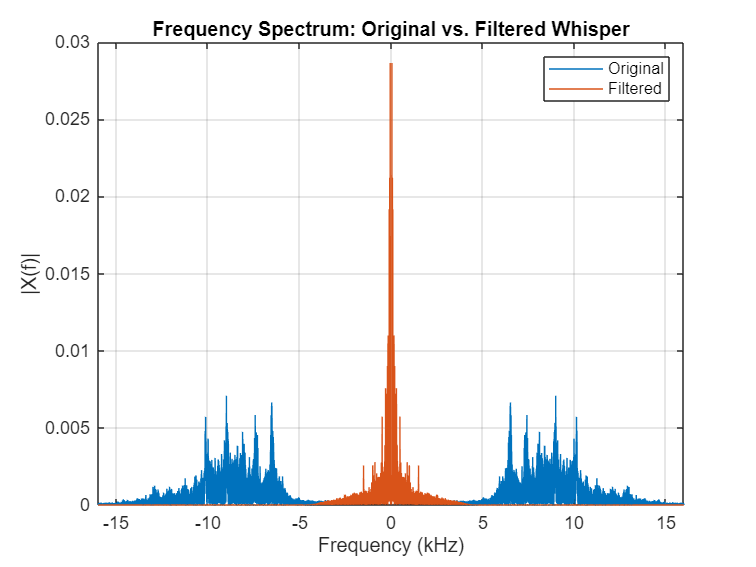

[~, xf_low_filtered, ~] = ftr(t, x_low_filtered, T, 'fft');

figure;
plot(f/1000, abs(xf_original_low)); hold on;
plot(f/1000, abs(xf_low_filtered));
xlabel('Frequency (kHz)');
ylabel('|X(f)|');
title('Frequency Spectrum: Original vs. Filtered Whisper');
legend('Original','Filtered');
xlim([-16, 16]);
grid on;

x_low_filtered = x_low_filtered / max(abs(x_low_filtered));
audiowrite('../audios/whisper_filtered_lowpass.wav', x_low_filtered, fs_low);